clear; close all;

## Обработка во временной области

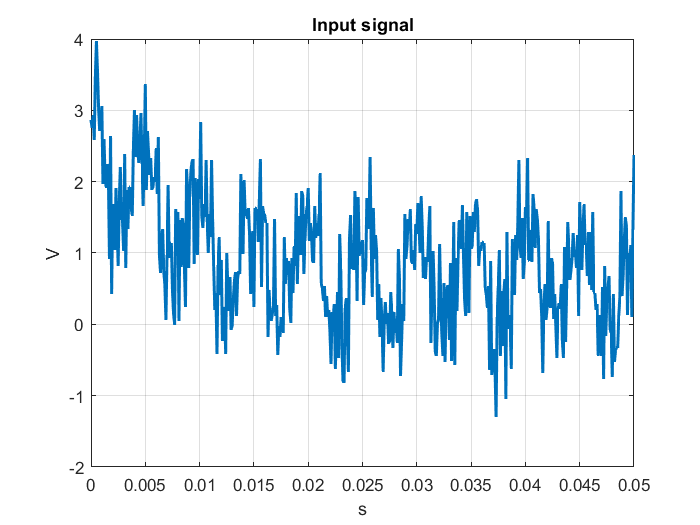

fs = 10e3;
dt = 1/fs;
alpha = 100;
Time = 0:dt:5/alpha;
N = length(Time);

T = 1/alpha/2;
q = 2;
tau = T/q;
d = [0 T 2*T 3*T 4*T 5*T 6*T 7*T 8*T 9*T 10*T]';
d(:,2) = ones(11,1);
A = 0.0;
Ideal = 1*pulstran(Time,d,'rectpuls',tau)-A;
Input = 2*exp(-alpha*Time)+Ideal;
Input = Input+0.5*randn(1,N);
plot(Time,Input,'-','LineWidth',1.5); grid;
xlim([Time(1) Time(end)]); xlabel('s');
ylabel('V'); title('Input signal');

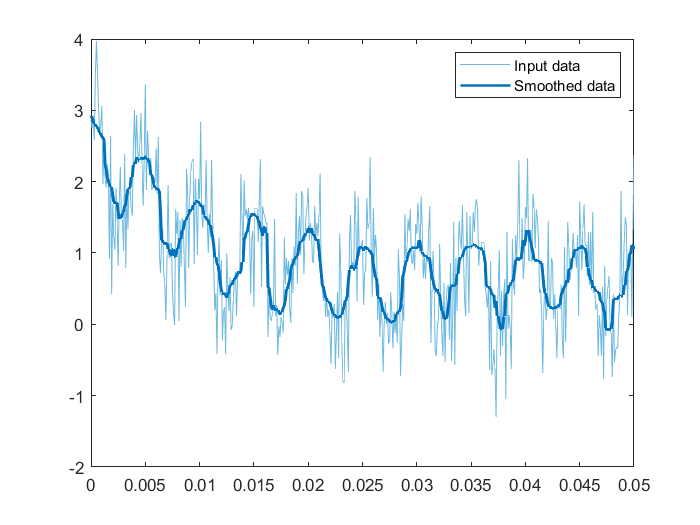

% Smooth input data
ClearedSignal = smoothdata(Input,'movmedian',0.0022,'SamplePoints',Time);

% Display results
clf
plot(Time,Input,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(Time,ClearedSignal,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

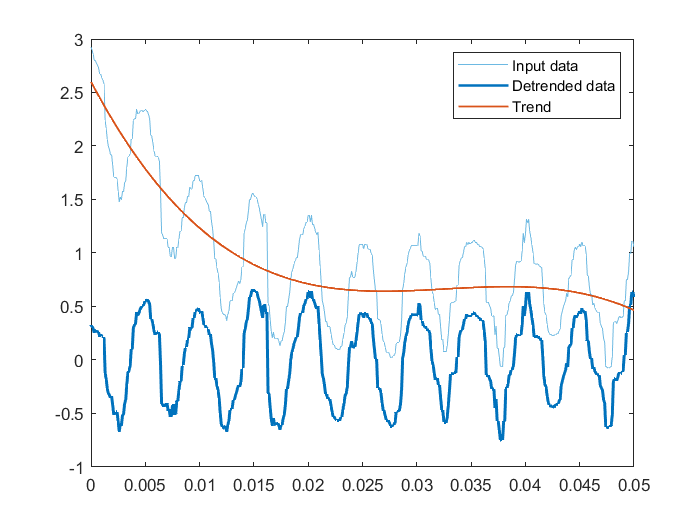

% Remove trend from data
DetrendedSignal = detrend(ClearedSignal,4,'SamplePoints',Time);

% Display results
clf
plot(Time,ClearedSignal,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(Time,DetrendedSignal,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(Time,ClearedSignal-DetrendedSignal,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend

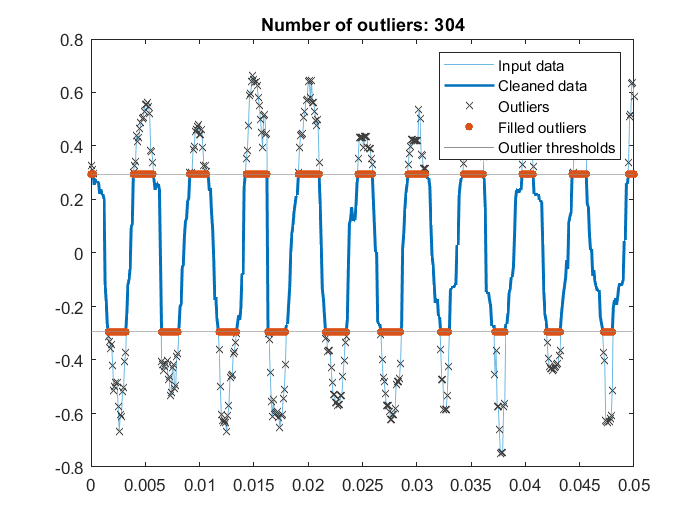

% Fill outliers
[CutedSignal,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(DetrendedSignal,'clip','mean','ThresholdFactor',0.75,...
    'SamplePoints',Time);

% Display results
clf
plot(Time,DetrendedSignal,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on
plot(Time,CutedSignal,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(Time(outlierIndices),DetrendedSignal(outlierIndices),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Plot filled outliers
plot(Time(outlierIndices),CutedSignal(outlierIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices thresholdLow thresholdHigh

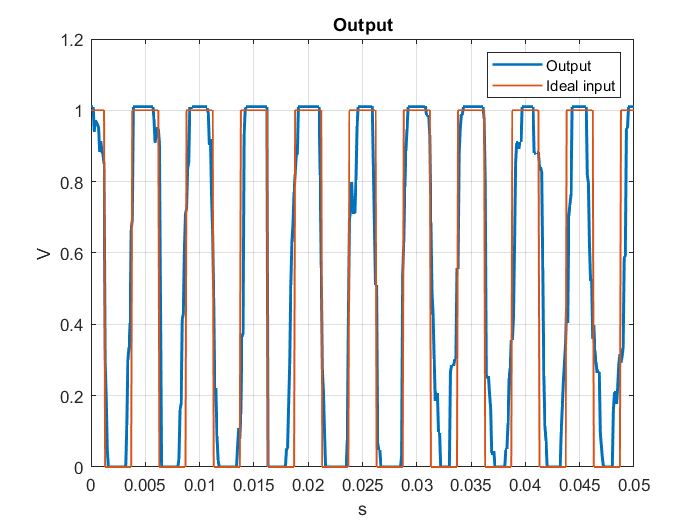

level = statelevels(CutedSignal);
level = max(abs(level));
lvl = 0.5/level;
CutedSignal = lvl*CutedSignal;
if A == 0
    Output = CutedSignal+abs(min(CutedSignal));
else
    Output = CutedSignal;
end
plot(Time,Output,'LineWidth',1.5); grid;
line(Time,Ideal,'Color',[0.85 0.325 0.098],'LineWidth',1);
xlabel('s'); ylabel('V'); title('Output');
legend('Output','Ideal input');

## Частотный эквивалент

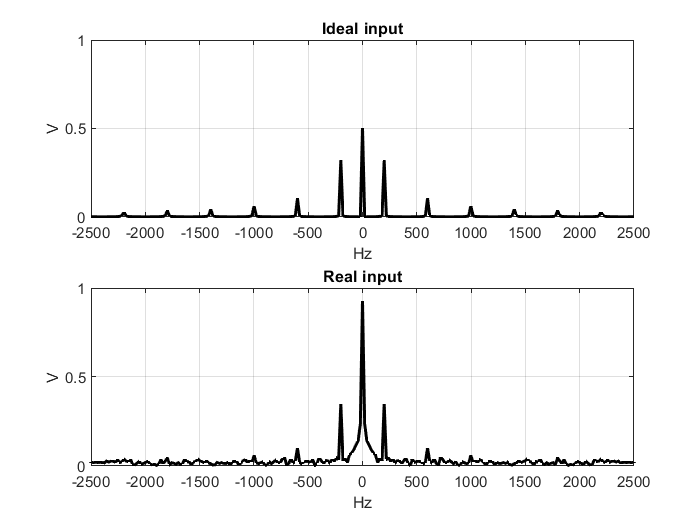

df = fs/N;
if mod(N,2)==1
    f = -(N-1)/2:(N-1)/2;
    f = f*df;
else
    f = -N/2:N/2-1;
    f = f*df;
end
FFTIdeal = abs(fftshift(fft(Ideal)))/N;
FFTInput = abs(fftshift(fft(Input)))/N;
FFTClearedSignal = abs(fftshift(fft(ClearedSignal)))/N;
FFTDetrendedSignal = abs(fftshift(fft(DetrendedSignal)))/N;
FFTCutedSignal = abs(fftshift(fft(CutedSignal)))/N;
FFTOutput = abs(fftshift(fft(Output)))/N;

subplot(2,1,1);
plot(f,FFTIdeal,'-k','LineWidth',1.5); grid;
xlabel('Hz'); ylabel('V'); title('Ideal input');
xlim([-fs/4 fs/4]); ylim([0 1]);
subplot(2,1,2);
plot(f,FFTInput,'-k','LineWidth',1.5); grid;
xlabel('Hz'); ylabel('V'); title('Real input');
xlim([-fs/4 fs/4]); ylim([0 1]);

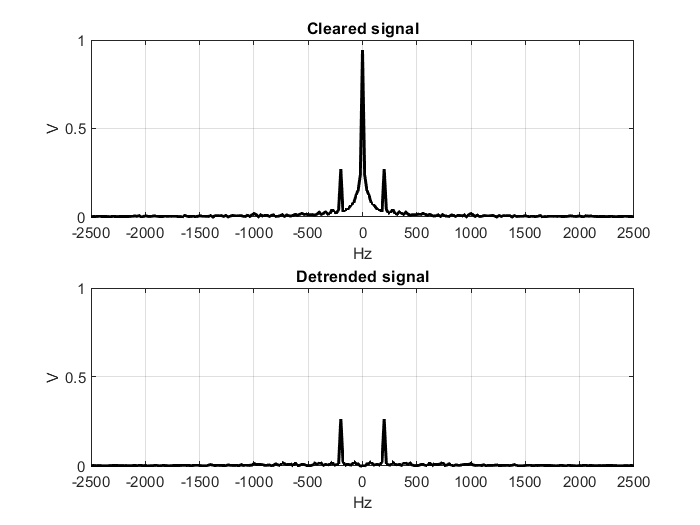

subplot(2,1,1);
plot(f,FFTClearedSignal,'-k','LineWidth',1.5); grid;
xlabel('Hz'); ylabel('V'); title('Cleared signal');
xlim([-fs/4 fs/4]); ylim([0 1]);
subplot(2,1,2);
plot(f,FFTDetrendedSignal,'-k','LineWidth',1.5); grid;
xlabel('Hz'); ylabel('V'); title('Detrended signal');
xlim([-fs/4 fs/4]); ylim([0 1]);

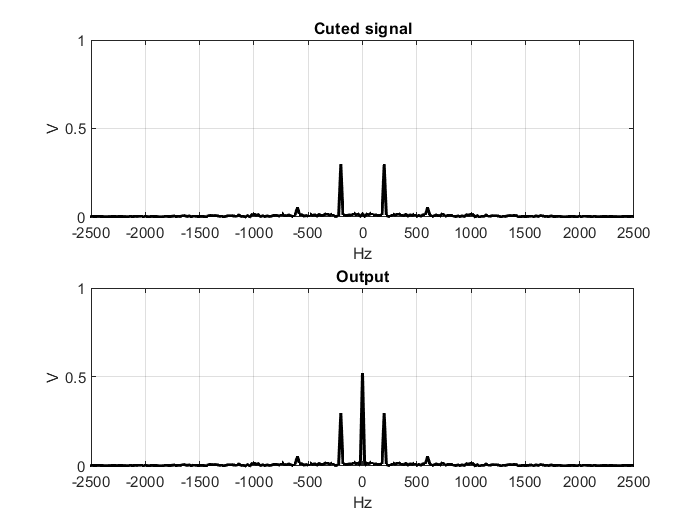

subplot(2,1,1);
plot(f,FFTCutedSignal,'-k','LineWidth',1.5); grid;
xlabel('Hz'); ylabel('V'); title('Cuted signal');
xlim([-fs/4 fs/4]); ylim([0 1]);
subplot(2,1,2);
plot(f,FFTOutput,'-k','LineWidth',1.5); grid;
xlabel('Hz'); ylabel('V'); title('Output');
xlim([-fs/4 fs/4]); ylim([0 1]);

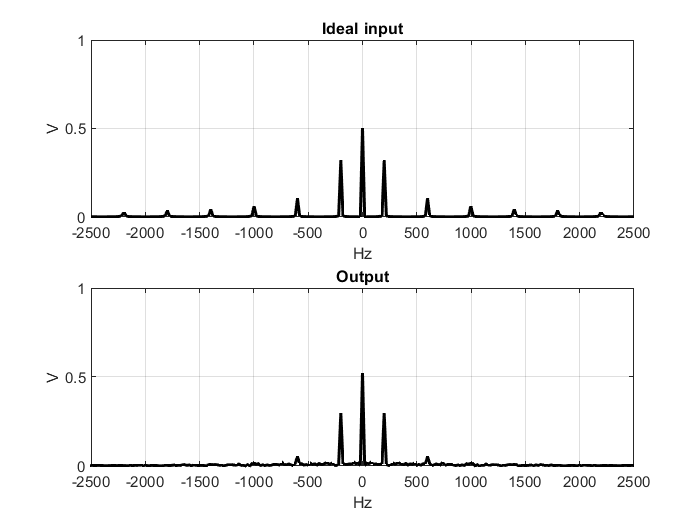

subplot(2,1,1);
plot(f,FFTIdeal,'-k','LineWidth',1.5); grid;
xlabel('Hz'); ylabel('V'); title('Ideal input');
xlim([-fs/4 fs/4]); ylim([0 1]);
subplot(2,1,2);
plot(f,FFTOutput,'-k','LineWidth',1.5); grid;
xlabel('Hz'); ylabel('V'); title('Output');
xlim([-fs/4 fs/4]); ylim([0 1]);